% Tensor Component Analysis (TCA): via Canonical Polyadic Decomposition
% (CPD) - Factor Analysis
clear;

if exist('H:\', 'dir')  % If H:\ exists, assume this is Computer 1
    input_path = 'H:\My Drive\Data\New Data\EEG epoched\BLT';
    output_path = 'C:\Users\sinad\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';

elseif exist('G:\', 'dir')  % If G:\ exists, assume this is Computer 2
    input_path = 'G:\My Drive\Data\New Data\EEG epoched\BLT';
    output_path = 'C:\Users\sdabiri\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';
else
    error('Unknown system: Cannot determine input and output paths.');
end

condition = ['BLT'];
file_path = fullfile(input_path,'binepochs filtered ICArej BLTAvgBOS2.set');
EEG = pop_loadset(file_path);

pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS2.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS2.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...



cpd_input_path = fullfile(output_path,condition);
U_pre = load(fullfile(cpd_input_path,"Bos2_U_pre.mat")).U_pre;
U_post = load(fullfile(cpd_input_path,"Bos2_U_post.mat")).U_post;


fs = EEG.srate; % Sampling rate
time_vector = linspace(-0.5, 3, size(EEG.data, 2)); % Time axis (-500ms to 3000ms)

% - Bandpass filter different EEG bands (theta, alpha, beta, gamma): Here
% we will first focus on beta for its role in attention.
epoch_trials = 1:2:EEG.trials; % Select odd trials
num_trials = length(epoch_trials);

% % Bandpass filter beta band (13-30 Hz)
% beta_band = [13 30];
% beta_signal = zeros(size(data)); % Preallocate
% for epoch = 1:size(data, 3)
%     beta_signal(:,:,epoch) = bandpass(data(:,:,epoch)', beta_band, fs)'; % ch x time x trial
% end

% Define pre- and post-stimulus time windows (400ms before and after stimulus onset at 1020ms)
% 512 sample/sec x 0.4 sec = 204.8
% Define pre-stimulus window (same for both conditions)
pre_window = [-0.4, 0];
post_window = [0, 0.4];

% % Convert time to indices
pre_idx = find(time_vector >= pre_window(1) & time_vector <= pre_window(2));
post_idx = find(time_vector >= post_window(1) & time_vector <= post_window(2));

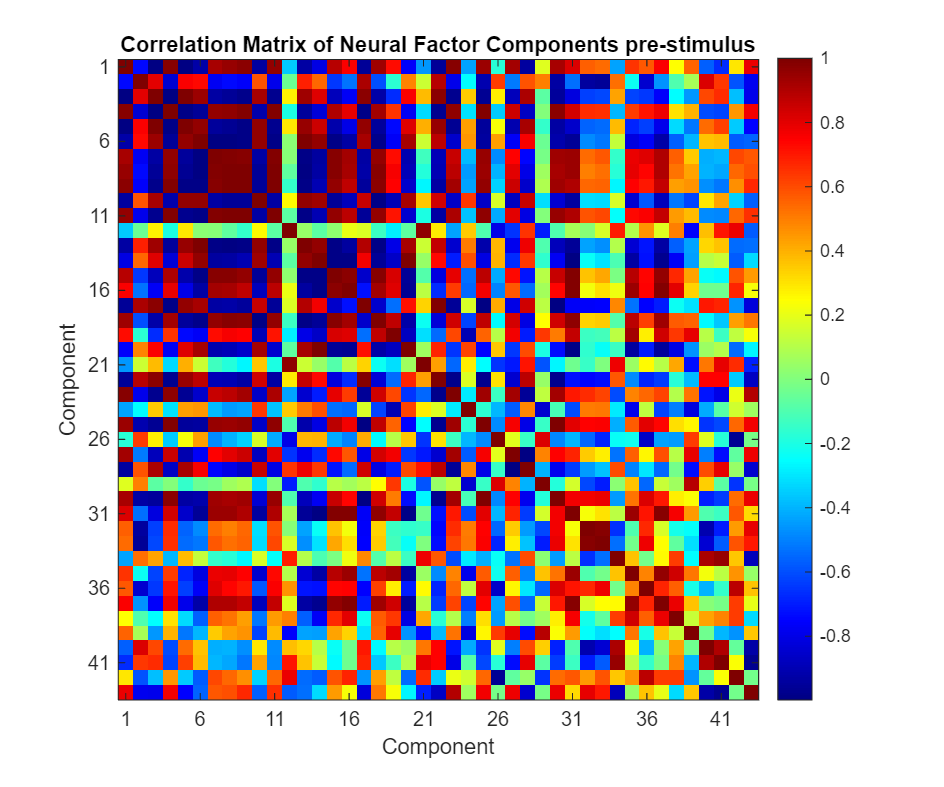

% Factor Analysis: The neuron factor correlation matrix

% Create correlation matrix for neural factor U_pre{1}
% Each column in U_pre{1} represents a component, so we compute correlations between components
correlation_matrix_pre = corrcoef(U_pre{1});

% Plot the correlation matrix
figure('Position', [100, 100, 600, 500]);
imagesc(correlation_matrix_pre);
colormap('jet');
colorbar;
axis square;
title('Correlation Matrix of Neural Factor Components pre-stimulus');
xlabel('Component');
ylabel('Component');

% Add component numbers to the tick labels
num_components_pre = size(correlation_matrix_pre, 1);
xticks(1:num_components_pre);
yticks(1:num_components_pre);

% If there are many components, you might want to show tick labels at intervals
if num_components_pre > 20
    xticks(1:5:num_components_pre);
    yticks(1:5:num_components_pre);
end

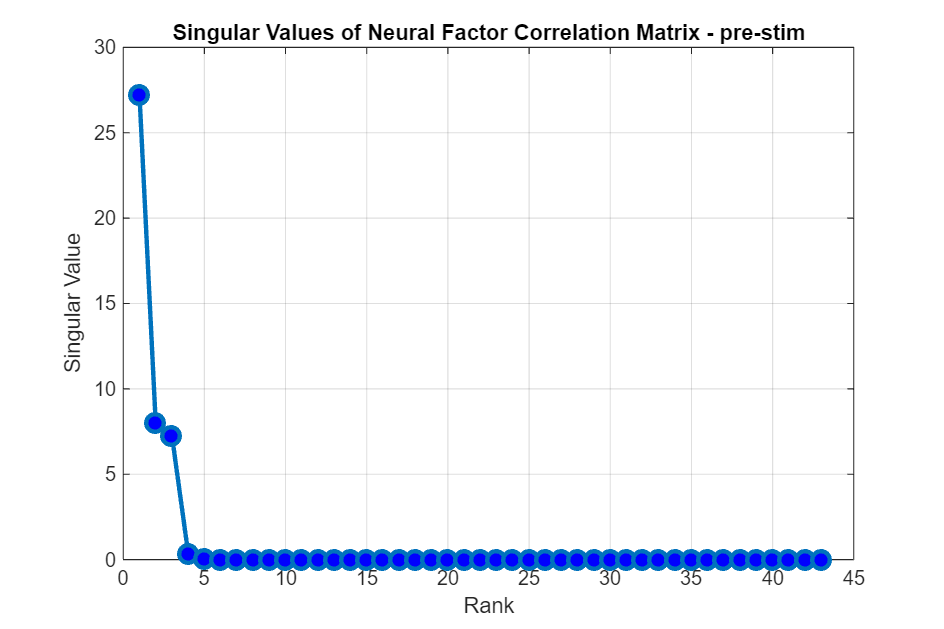

% Perform SVD on the correlation matrix of neural factors
% correlation_matrix_pre = corrcoef(U_pre{1});

% Apply SVD
[Un_pre, S_pre, V_pre] = svd(correlation_matrix_pre);

% Extract singular values (diagonal elements of S)
singular_values_pre = diag(S_pre);

% Plot singular values vs. rank
figure('Position', [100, 100, 600, 400]);
plot(1:length(singular_values_pre), singular_values_pre, 'o-', 'LineWidth', 2, 'MarkerSize', 8, 'MarkerFaceColor', 'b');
xlabel('Rank');
ylabel('Singular Value');
title('Singular Values of Neural Factor Correlation Matrix - pre-stim');
grid on;

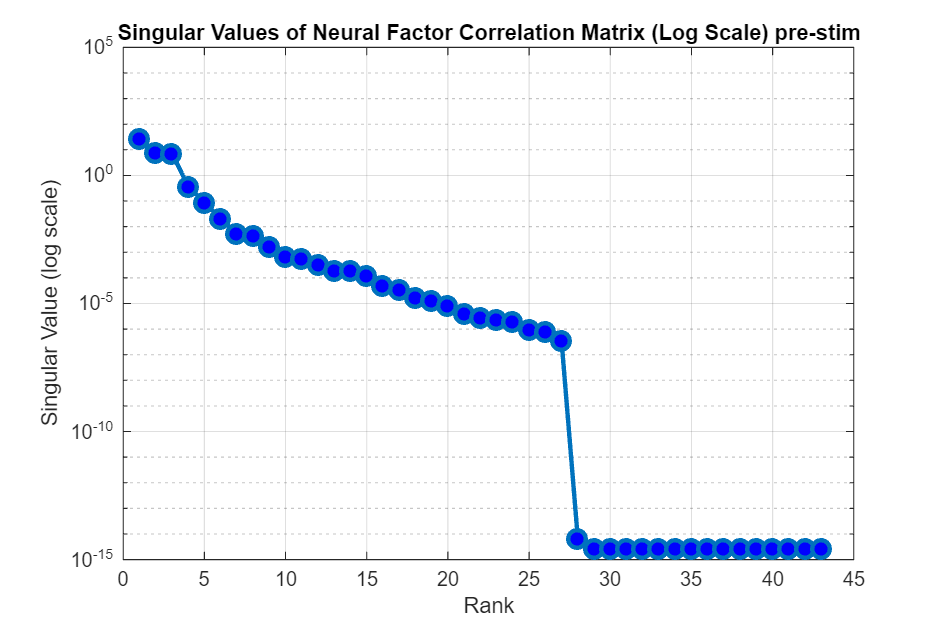


% Add log-scale version (often useful for seeing trend across all values)
figure('Position', [100, 100, 600, 400]);
semilogy(1:length(singular_values_pre), singular_values_pre, 'o-', 'LineWidth', 2, 'MarkerSize', 8, 'MarkerFaceColor', 'b');
xlabel('Rank');
ylabel('Singular Value (log scale)');
title('Singular Values of Neural Factor Correlation Matrix (Log Scale) pre-stim');
grid on;

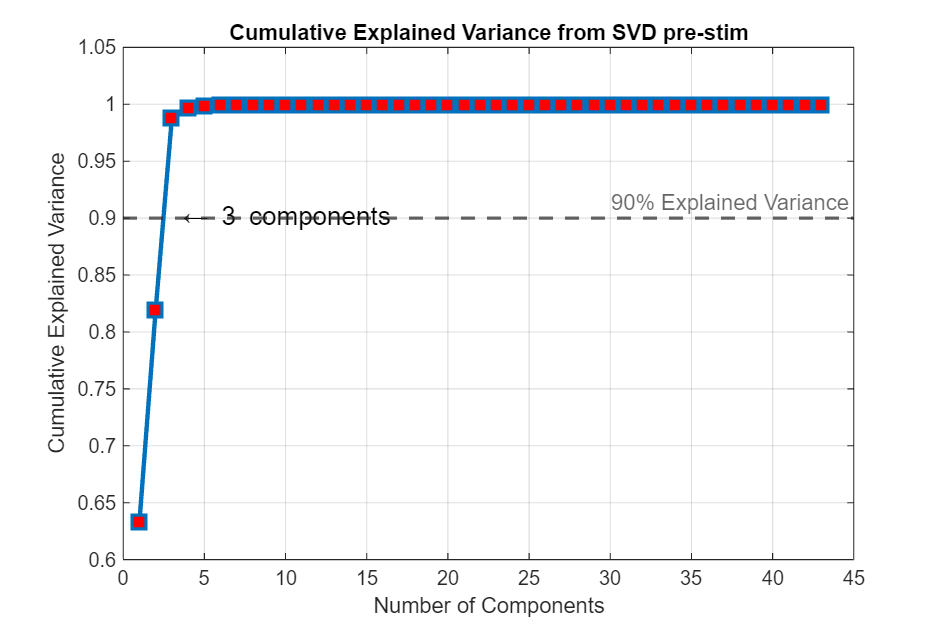


% Calculate cumulative explained variance
explained_variance_pre = singular_values_pre / sum(singular_values_pre);
cumulative_variance_pre = cumsum(explained_variance_pre);

% Plot cumulative explained variance
figure('Position', [100, 100, 600, 400]);
plot(1:length(cumulative_variance_pre), cumulative_variance_pre, 's-', 'LineWidth', 2, 'MarkerSize', 8, 'MarkerFaceColor', 'r');
hold on;
% Add horizontal line at 90% explained variance
yline(0.9, '--', '90% Explained Variance', 'LineWidth', 1.5);
xlabel('Number of Components');
ylabel('Cumulative Explained Variance');
title('Cumulative Explained Variance from SVD pre-stim');
grid on;

% Find number of components needed to explain 90% of variance
components_90pct_pre = find(cumulative_variance_pre >= 0.9, 1);
text(components_90pct_pre + 0.5, 0.9, ['\leftarrow ' num2str(components_90pct_pre) ' components'], 'FontSize', 12);

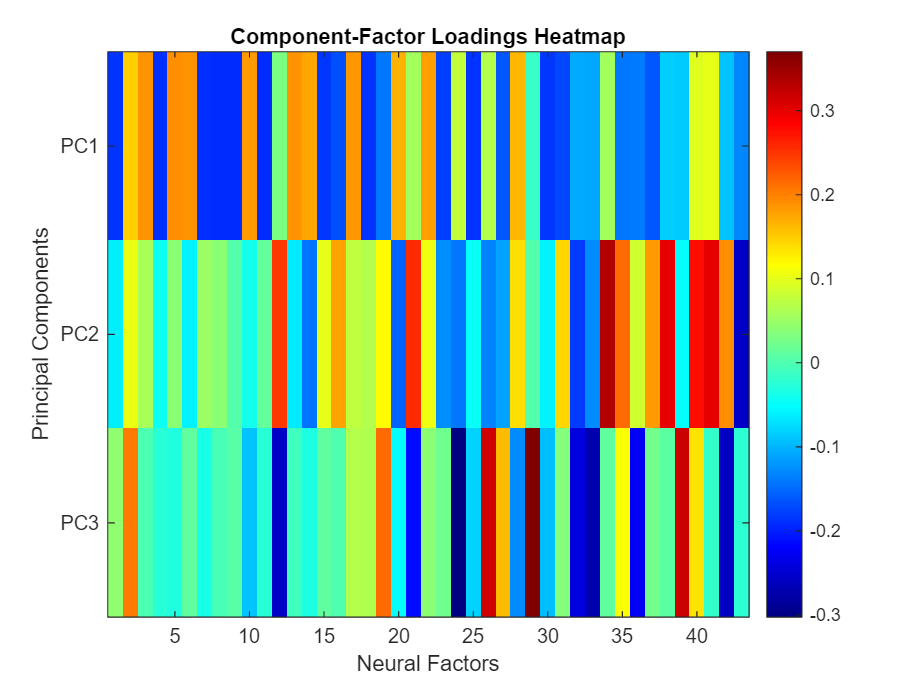

figure;
imagesc(V_pre(:,1:3)');  % Transpose to get components as rows
colormap(jet);
colorbar;
xlabel('Neural Factors');
ylabel('Principal Components');
title('Component-Factor Loadings Heatmap');
set(gca, 'YTick', 1:3, 'YTickLabel', {'PC1', 'PC2', 'PC3'});

for i = 1:3  % For each of your top 3 components
    [sortedValues_pre, sortedIndices_pre] = sort(abs(V_pre(:,i)), 'descend');
    fprintf('Principal Component %d - Top contributing factors:\n', i);
    for j = 1:min(10, length(sortedIndices_pre))  % Show top 10 factors
        fprintf('  Factor %d: Loading = %.4f\n', sortedIndices_pre(j), V_pre(sortedIndices_pre(j),i));
    end
    fprintf('\n');
end

Principal Component 1 - Top contributing factors:


  Factor 9: Loading = -0.1910
  Factor 11: Loading = -0.1901
  Factor 8: Loading = -0.1898
  Factor 5: Loading = 0.1892
  Factor 4: Loading = -0.1891
  Factor 6: Loading = 0.1888
  Factor 7: Loading = -0.1886
  Factor 13: Loading = 0.1875
  Factor 3: Loading = 0.1875
  Factor 1: Loading = -0.1863


Principal Component 2 - Top contributing factors:


  Factor 34: Loading = 0.3339
  Factor 38: Loading = 0.2997
  Factor 41: Loading = 0.2994
  Factor 40: Loading = 0.2764
  Factor 43: Loading = -0.2568
  Factor 21: Loading = 0.2558
  Factor 12: Loading = 0.2467
  Factor 35: Loading = 0.2137
  Factor 42: Loading = 0.1892
  Factor 37: Loading = 0.1818


Principal Component 3 - Top contributing factors:


  Factor 29: Loading = 0.3702
  Factor 39: Loading = 0.3196
  Factor 26: Loading = 0.3162
  Factor 24: Loading = -0.3025
  Factor 33: Loading = -0.2729
  Factor 42: Loading = -0.2589
  Factor 12: Loading = -0.2577
  Factor 32: Loading = -0.2421
  Factor 36: Loading = -0.2251
  Factor 19: Loading = 0.2147


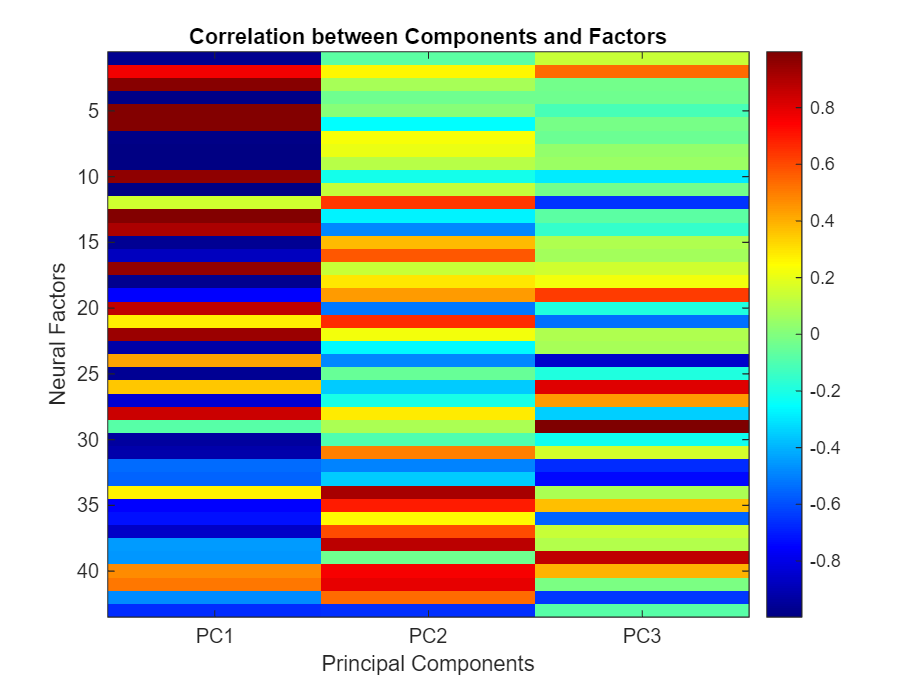

% Assuming U_pre{1} is your original data matrix and U, S, V are from your SVD
componentScores_pre = U_pre{1} * V_pre(:,1:3);  % Project data onto first 3 components

% Calculate correlations between component scores and original factors
correlationMatrix_pre = corr(componentScores_pre, U_pre{1});

figure;
imagesc(correlationMatrix_pre');
colormap(jet);
colorbar;
xlabel('Principal Components');
ylabel('Neural Factors');
title('Correlation between Components and Factors');
set(gca, 'XTick', 1:3, 'XTickLabel', {'PC1', 'PC2', 'PC3'});

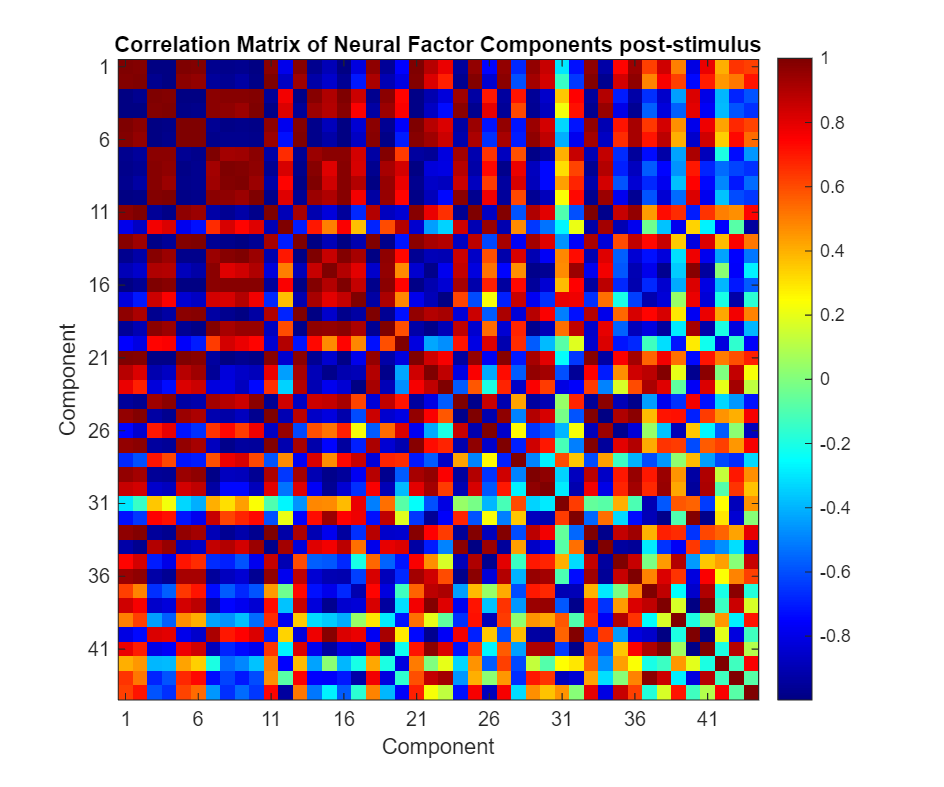

% Create correlation matrix for neural factor U_post{1}
% Each column in U_post{1} represents a component, so we compute correlations between components
correlation_matrix_post = corrcoef(U_post{1});

% Plot the correlation matrix
figure('Position', [100, 100, 600, 500]);
imagesc(correlation_matrix_post);
colormap('jet');
colorbar;
axis square;
title('Correlation Matrix of Neural Factor Components post-stimulus');
xlabel('Component');
ylabel('Component');

% Add component numbers to the tick labels
num_components_post = size(correlation_matrix_post, 1);
xticks(1:num_components_post);
yticks(1:num_components_post);

% If there are many components, you might want to show tick labels at intervals
if num_components_post > 20
    xticks(1:5:num_components_post);
    yticks(1:5:num_components_post);
end

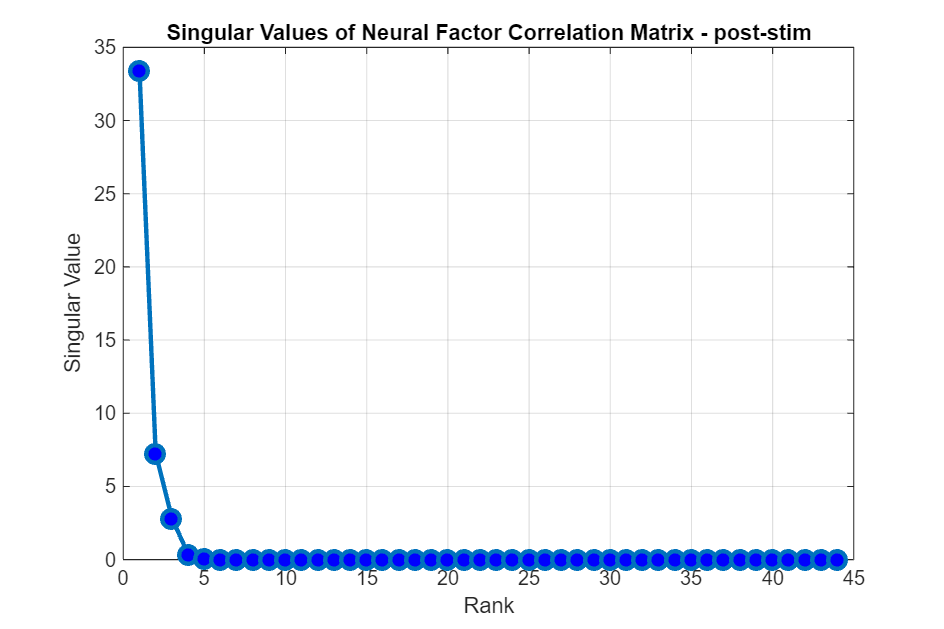



% Perform SVD on the correlation matrix of neural factors
correlation_matrix_post = corrcoef(U_post{1});

% Apply SVD
[Un_post, S_post, V_post] = svd(correlation_matrix_post);

% Extract singular values (diagonal elements of S)
singular_values_post = diag(S_post);

% Plot singular values vs. rank
figure('Position', [100, 100, 600, 400]);
plot(1:length(singular_values_post), singular_values_post, 'o-', 'LineWidth', 2, 'MarkerSize', 8, 'MarkerFaceColor', 'b');
xlabel('Rank');
ylabel('Singular Value');
title('Singular Values of Neural Factor Correlation Matrix - post-stim');
grid on;

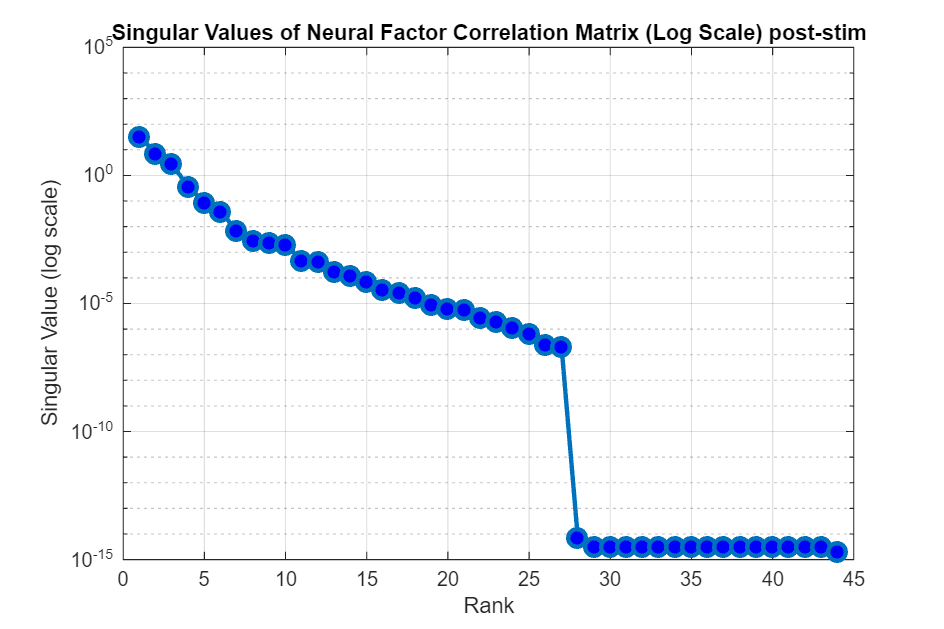


% Add log-scale version (often useful for seeing trend across all values)
figure('Position', [100, 100, 600, 400]);
semilogy(1:length(singular_values_post), singular_values_post, 'o-', 'LineWidth', 2, 'MarkerSize', 8, 'MarkerFaceColor', 'b');
xlabel('Rank');
ylabel('Singular Value (log scale)');
title('Singular Values of Neural Factor Correlation Matrix (Log Scale) post-stim');
grid on;

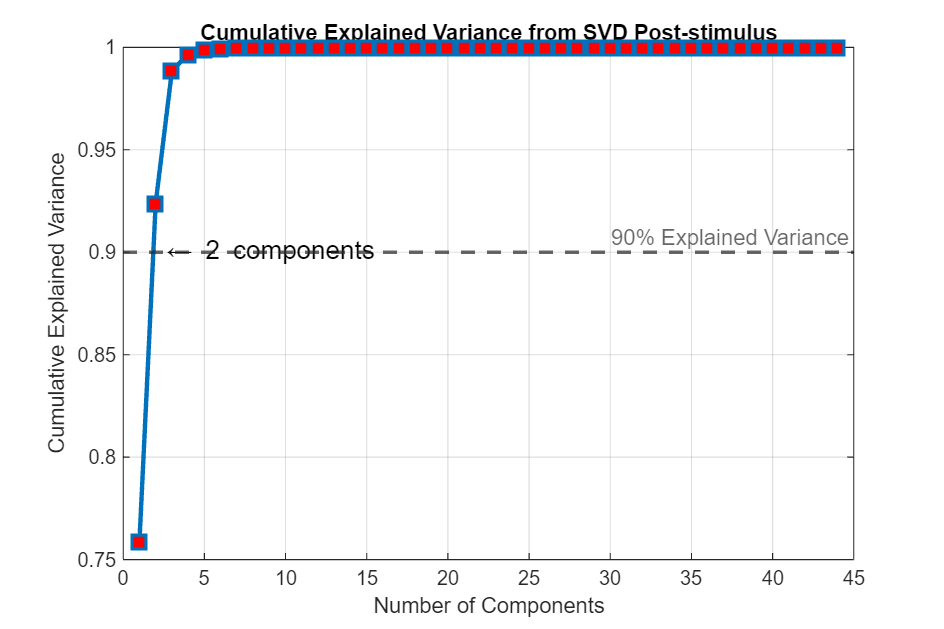


% Calculate cumulative explained variance
explained_variance_post = singular_values_post / sum(singular_values_post);
cumulative_variance_post = cumsum(explained_variance_post);

% Plot cumulative explained variance
figure('Position', [100, 100, 600, 400]);
plot(1:length(cumulative_variance_post), cumulative_variance_post, 's-', 'LineWidth', 2, 'MarkerSize', 8, 'MarkerFaceColor', 'r');
hold on;
% Add horizontal line at 90% explained variance
yline(0.9, '--', '90% Explained Variance', 'LineWidth', 1.5);
xlabel('Number of Components');
ylabel('Cumulative Explained Variance');
title('Cumulative Explained Variance from SVD Post-stimulus');
grid on;

% Find number of components needed to explain 90% of variance
components_90pct_post = find(cumulative_variance_post >= 0.9, 1);
text(components_90pct_post + 0.5, 0.9, ['\leftarrow ' num2str(components_90pct_post) ' components'], 'FontSize', 12);

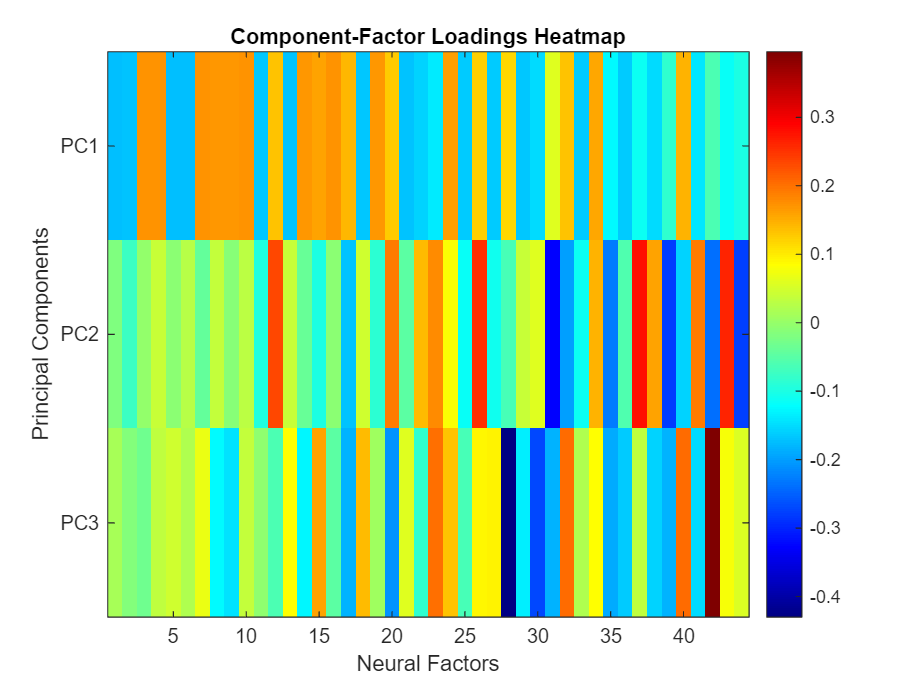

figure;
imagesc(V_post(:,1:3)');  % Transpose to get components as rows
colormap(jet);
colorbar;
xlabel('Neural Factors');
ylabel('Principal Components');
title('Component-Factor Loadings Heatmap');
set(gca, 'YTick', 1:3, 'YTickLabel', {'PC1', 'PC2', 'PC3'});

for i = 1:3  % For each of your top 3 components
    [sortedValues_post, sortedIndices_post] = sort(abs(V_post(:,i)), 'descend');
    fprintf('Principal Component %d - Top contributing factors:\n', i);
    for j = 1:min(10, length(sortedIndices_post))  % Show top 10 factors
        fprintf('  Factor %d: Loading = %.4f\n', sortedIndices_post(j), V_post(sortedIndices_post(j),i));
    end
    fprintf('\n');
end

Principal Component 1 - Top contributing factors:


  Factor 1: Loading = -0.1727
  Factor 3: Loading = 0.1727
  Factor 6: Loading = -0.1724
  Factor 5: Loading = -0.1723
  Factor 16: Loading = 0.1723
  Factor 10: Loading = 0.1720
  Factor 4: Loading = 0.1717
  Factor 21: Loading = -0.1706
  Factor 7: Loading = 0.1704
  Factor 13: Loading = -0.1703


Principal Component 2 - Top contributing factors:


  Factor 31: Loading = -0.3276
  Factor 39: Loading = -0.2789
  Factor 37: Loading = 0.2779
  Factor 44: Loading = -0.2754
  Factor 43: Loading = 0.2619
  Factor 26: Loading = 0.2511
  Factor 42: Loading = -0.2367
  Factor 12: Loading = 0.2337
  Factor 35: Loading = -0.2290
  Factor 32: Loading = -0.1990


Principal Component 3 - Top contributing factors:


  Factor 28: Loading = -0.4300
  Factor 42: Loading = 0.3959
  Factor 30: Loading = -0.2692
  Factor 20: Loading = -0.2078
  Factor 32: Loading = 0.2045
  Factor 40: Loading = 0.2030
  Factor 23: Loading = 0.1991
  Factor 35: Loading = -0.1910
  Factor 17: Loading = -0.1833
  Factor 31: Loading = -0.1825


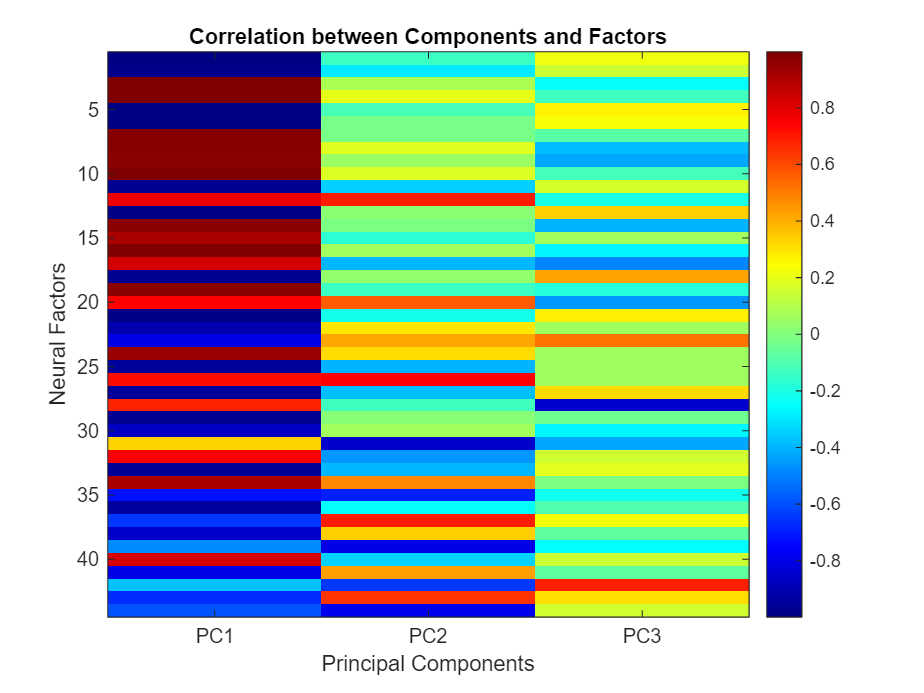

% Assuming U_pre{1} is your original data matrix and U, S, V are from your SVD
componentScores_post = U_post{1} * V_post(:,1:3);  % Project data onto first 3 components

% Calculate correlations between component scores and original factors
correlationMatrix_post = corr(componentScores_post, U_post{1});

figure;
imagesc(correlationMatrix_post');
colormap(jet);
colorbar;
xlabel('Principal Components');
ylabel('Neural Factors');
title('Correlation between Components and Factors');
set(gca, 'XTick', 1:3, 'XTickLabel', {'PC1', 'PC2', 'PC3'});